Estimación de parámetros directamente en Matlab

addpath(genpath("Functions"))
load("RealDataExamples/HareLynx.mat")
t = Years;

%Condiciones iniciales de estimación
%tetha0 = [condiciones_iniciales_ODE condicion_inicial_params]
theta0 = [20, 20, 1, 1, 1, 1]';

%Limites inferiores y superiores en la estimación
% de condiciones iniciales y parámetros
lb = [0 0 0 0 0 0];
ub = [200 200 10 10 10 10];

%proceso de estimación de parámetros
opt = optimoptions('lsqcurvefit',"Display","iter");
[theta] = lsqcurvefit(@PredatorPrey, theta0, t, [Prey, Predator], lb, ub, opt);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          7          348712                      5.02e+12
     1         14          345457    7.12811e-08        5.1e+12      
     2         21          345457     4.2666e-08        5.1e+12      

Local minimum possible.
lsqcurvefit stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


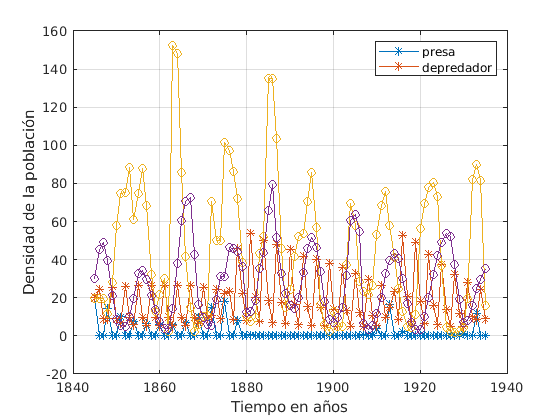


ysim =  PredatorPrey(theta, t);
plot(t,ysim, '-*')

hold on
plot(t, [Prey, Predator], '-o')
grid on
ylabel("Densidad de la población")
xlabel("Tiempo en años")
legend("presa", "depredador")

addpath(genpath("Tool"))
syms P(t) D(t)
syms alpha beta delta gamma

ode1 = diff(P) == alpha*P - beta*P*D;
ode2 = diff(D) == delta*D*P - gamma*D;
odes = [ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}P\left(t\right)=\alpha \,P\left(t\right)-\beta \,\text{D}\left(t\right)\,P\left(t\right)\\ \frac{\partial }{\partial t}\text{D}\left(t\right)=\delta \,\text{D}\left(t\right)\,P\left(t\right)-\gamma \,\text{D}\left(t\right) \end{array}\right)$$


vars = [P D];

domain = [Years(1) Years(end)];
xdata = Years;

modelName = 'Lotka-Volterra';
gsua_dataprep(odes, vars, domain, modelName);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccc} P\left(t\right) & \text{D}\left(t\right) & \alpha & \beta & \delta & \gamma \end{array}\right)$$


Ranges = [1 120;       %P(0)
          1 120;       %D(0)
          0 10;       %alpha
          0 10;       %beta
          0 10;       %delta 
          0 10        %gamma
          ];

[T, ~] = gsua_dataprep(odes, vars, domain, modelName, 'Range', Ranges);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccc} P\left(t\right) & \text{D}\left(t\right) & \alpha & \beta & \delta & \gamma \end{array}\right)$$

Generating a valid matrix for estimations
Estimation 1
Estimation 2
Estimation 3
Estimation 4
Estimation 5
Estimation 6
Estimation 7
Estimation 8
Estimation 9


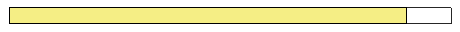

Estimation 10


T.Properties.CustomProperties.output = 1:2;

N = 100;

opt = optimoptions('lsqcurvefit', 'UseParallel',false,'Display','off');
solver = 'lsqc';

[T_est, ~] = gsua_pe(T, Years, [Prey, Predator], 'solver', solver, 'N', N, 'opt', opt); 

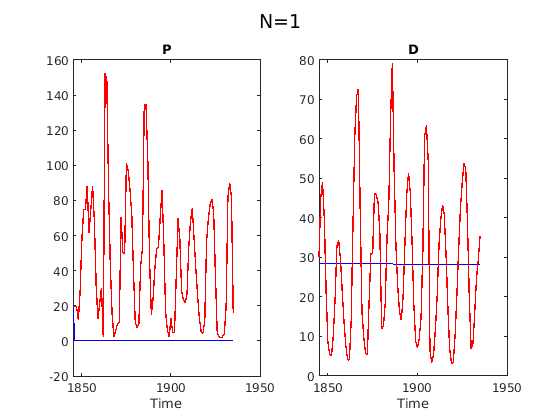

gsua_eval(T_est.Estlsqc(:,1), T_est, xdata', [Prey, Predator]');